## [1] Simulator Initialization

Initialize the simulator by setting default parameters for the attacker and defender

simulator = Simulator();
%setup the defender's chirp parameters

simulator.load_default_defender_params;
simulator.load_default_attacker_params;
simulator.Defender.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 65.00 MHz/us
	 Idle Time: 			 7.00 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 224 
	 ADC Sample Rate: 		 4.18 MSps
	 Ramp End Time: 		 60.85 us
	 Chirp Tx Bandwidth: 		 3955.25 MHz
	 Chirp Sampling Bandwidth: 	 3480.76 MHz
	 ADC Sampling Period: 		 53.55 us
	 Chirp Cycle Time: 		 67.85 us
	 Chirp Wavelength: 		 0.00 nm


simulator.Defender.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 16
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 1.09 ms


simulator.Defender.print_performance_specs;

Performance Specifications
	 Max Range 			 9.65 m
	 Range Resolution 		 0.04 m
	 Max Velocity 			 14.35 m/s
	 Velocity Resolution 		 1.79 m/s


simulator.Attacker.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 65.00 MHz/us
	 Idle Time: 			 7.00 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 256 
	 ADC Sample Rate: 		 13.04 MSps
	 Ramp End Time: 		 26.93 us
	 Chirp Tx Bandwidth: 		 1750.12 MHz
	 Chirp Sampling Bandwidth: 	 1275.63 MHz
	 ADC Sampling Period: 		 19.63 us
	 Chirp Cycle Time: 		 33.92 us
	 Chirp Wavelength: 		 0.00 nm


simulator.Attacker.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 32
	 FramePeriodicity 		 33.50 ms
	 Active Frame Time 		 1.09 ms


simulator.Attacker.print_performance_specs

Performance Specifications
	 Max Range 			 30.08 m
	 Range Resolution 		 0.12 m
	 Max Velocity 			 28.69 m/s
	 Velocity Resolution 		 1.79 m/s


## [2] Plot a specified chirp from a specified frame

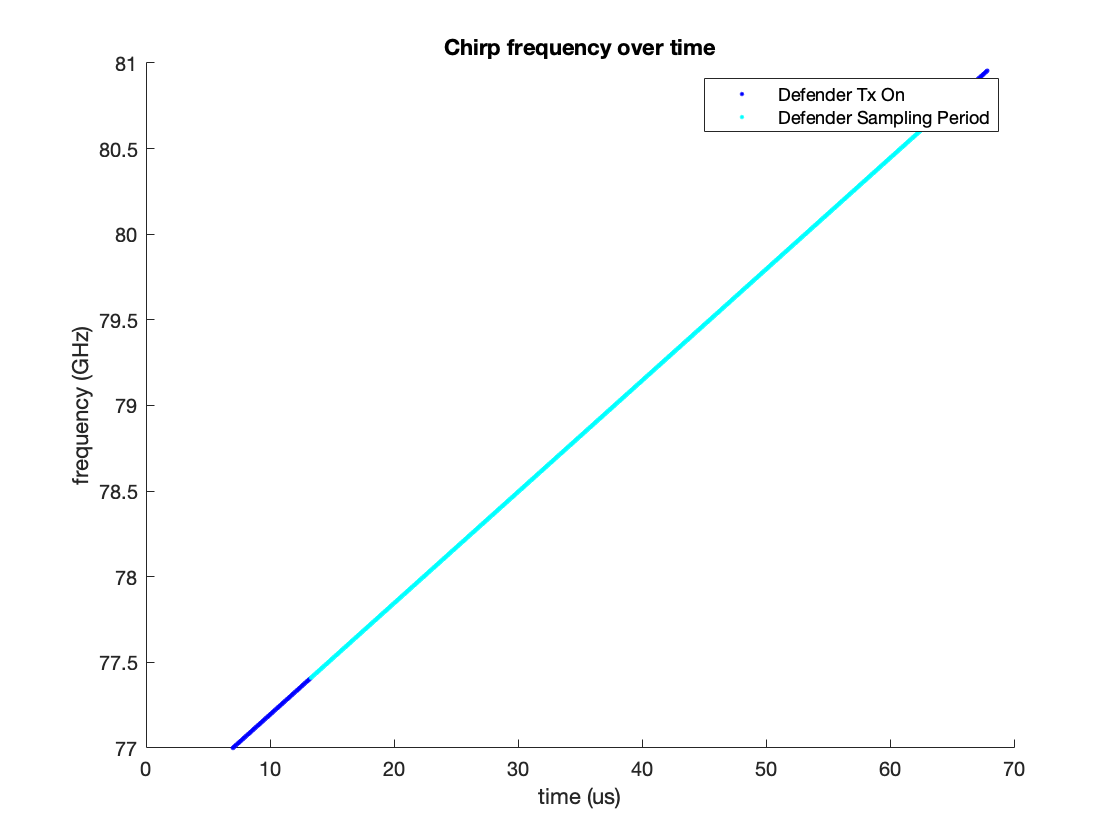

figure;
ax = axes;
specified_frame = 1;
specified_chirp = 1;
simulator.plot_specified_radar_chirp(ax,simulator.Defender,specified_frame, specified_chirp);
hold on;

## [3] Plotting Chirp for a False Positive Attack

In this example, there is no valid attack region as the attacker and defender chirps are not close enough

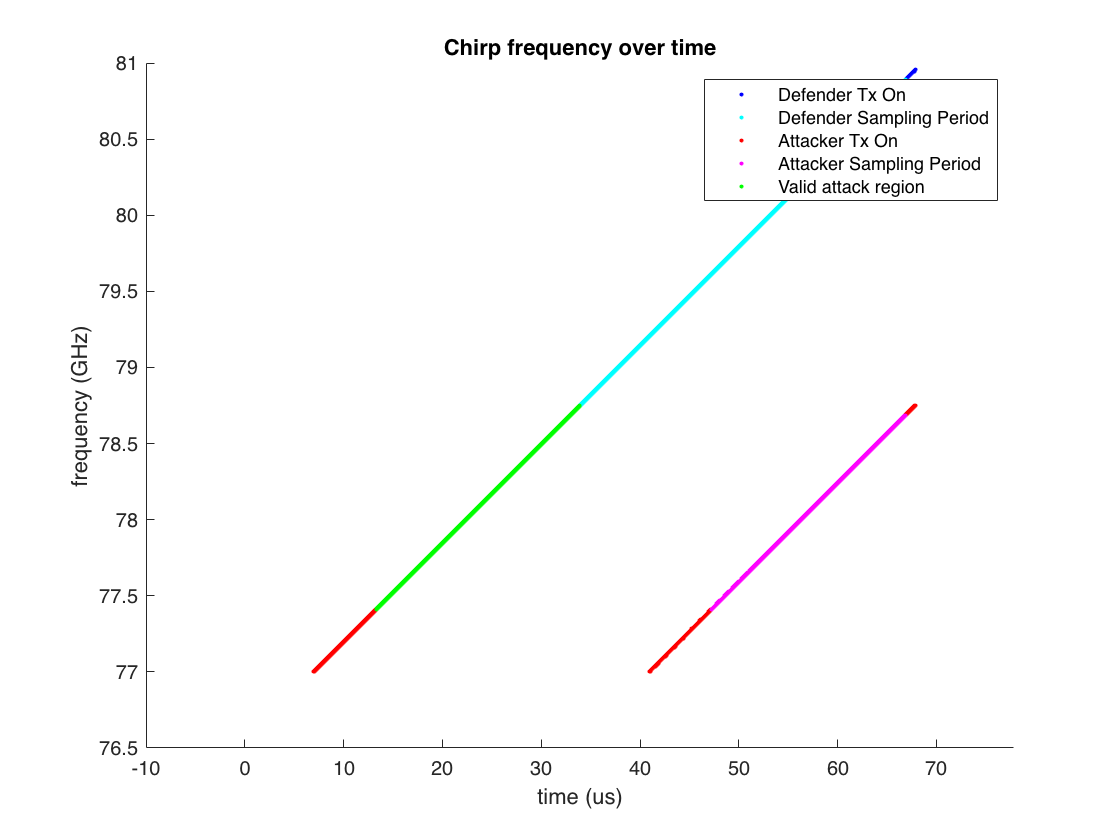

clf;
ax = axes;
defender_chirp = 1;
defender_frame = 1;
simulator.plot_attacker_and_defender_chirps(ax,defender_frame,defender_chirp);

## [4] Plot an desired radar frame

clf;
ax = axes;
specified_frame = 3;
simulator.plot_specified_radar_frame(ax,simulator.Defender,specified_frame);

## [5] Overlay any attacker frames that would interfere with a defender frame and identify regions that would qualify as valid attacks

Here, the green regions identify that the attacker is successfully interfering with the defender

clf;
ax = axes;
specified_frame = 1;
simulator.plot_attacker_and_defender_frames(ax,specified_frame)

## [6] Plotting Chirp For a False Negative Attack

clf;
ax = axes;
defender_chirp = 1;
defender_frame = 1;

simulator.load_default_defender_params;
simulator.load_attacker_scenario_2;

%apply a few offsets so that there is an intersection
simulator.Defender.timing_offset_us = 17;
simulator.plot_attacker_and_defender_chirps(ax,defender_frame,defender_chirp);

## [7] Generate the FMCW Waveform for a defender chirp and plot its spectogram

clf;
ax = axes;
simulator.configure_FMCW_parameters();

desired_frame = 1;
desired_chirp = 1;

simulator.FMCW_plot_radar_chirp_spectogram(ax,simulator.Defender,desired_frame,desired_chirp);

### [8] Simulated False Negative

simulated target at 5m

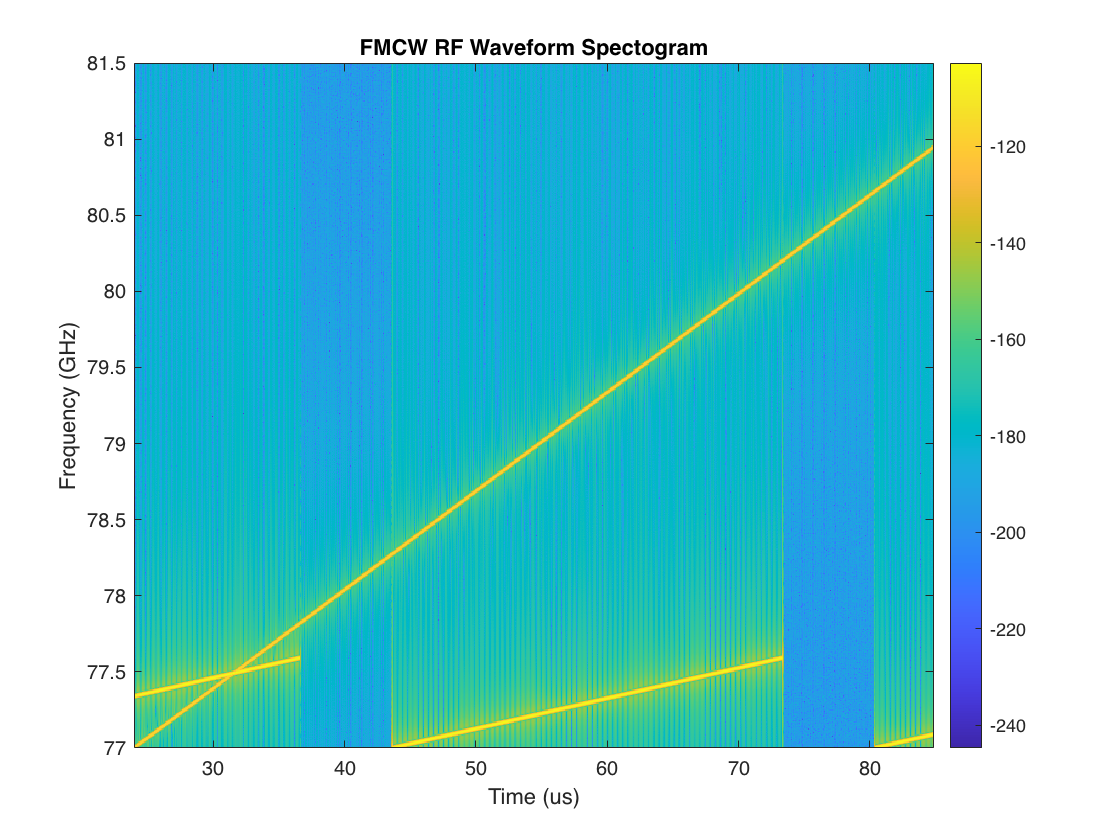

clf;
ax = axes;

simulator.load_default_defender_params;

%alternative setting
simulator.load_attacker_scenario_2;
simulator.Defender.timing_offset_us = 17;

simulator.configure_FMCW_parameters();

defender_frame = 1;
defender_chirp = 1;

%load default target, attacker, and defender positions and velocities
simulator.load_target_default();
simulator.load_default_attacker_and_defender_position_and_velocity();

[sampled_IF_sig,combined_received_sigs, defender_waveform_sig, defender_waveform_t] = simulator.FMCW_simulate_scenario_chirp(defender_chirp,defender_frame);
simulator.plot_RF_spectogram(ax,combined_received_sigs,simulator.Defender.FMCW_sampling_rate_Hz,defender_waveform_t);

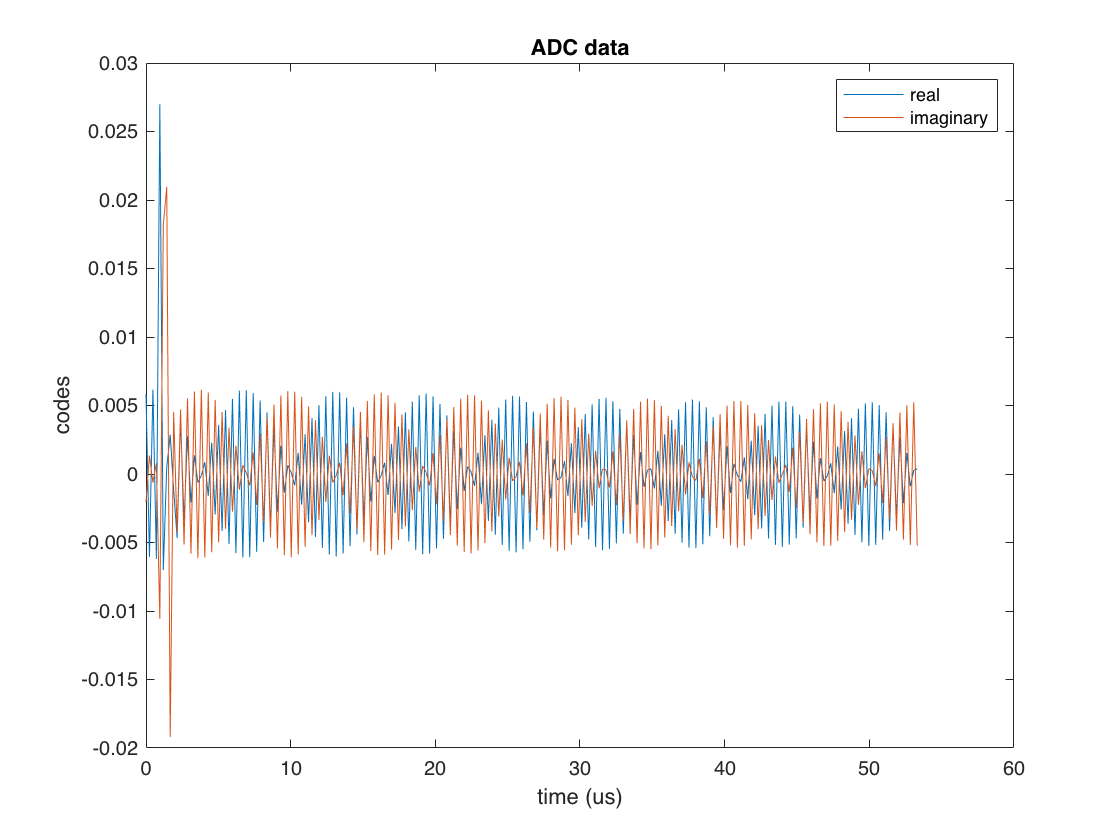

clf;
ax = axes;
simulator.FMCW_plot_sampled_IF_data(ax, simulator.Defender, sampled_IF_sig);

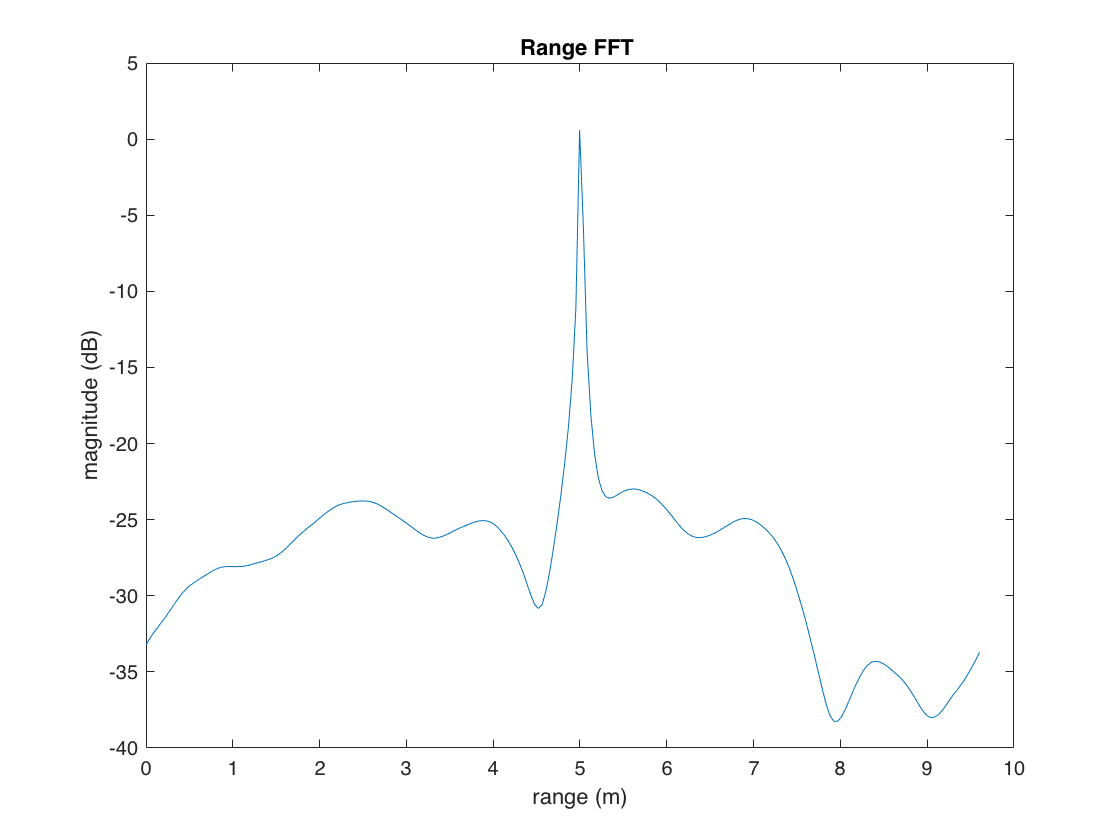

clf;
ax = axes;
simulator.FMCW_plot_range_fft(ax,simulator.Defender,sampled_IF_sig);

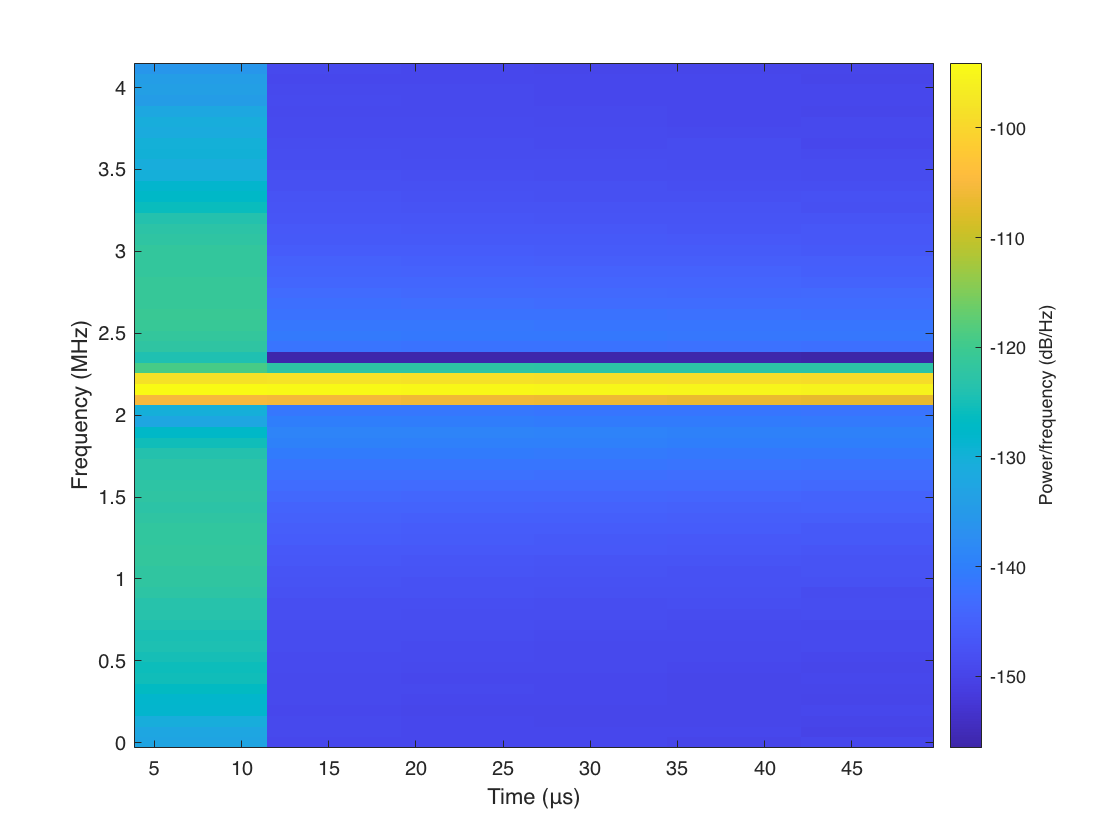

clf;
ax = axes;
simulator.plot_IF_spectogram(ax,sampled_IF_sig,simulator.Defender.ADC_SampleRate_MSps * 1e6);

## [9] Simulated False Positive Attack

Target placed at 5m, point gets added at 3m

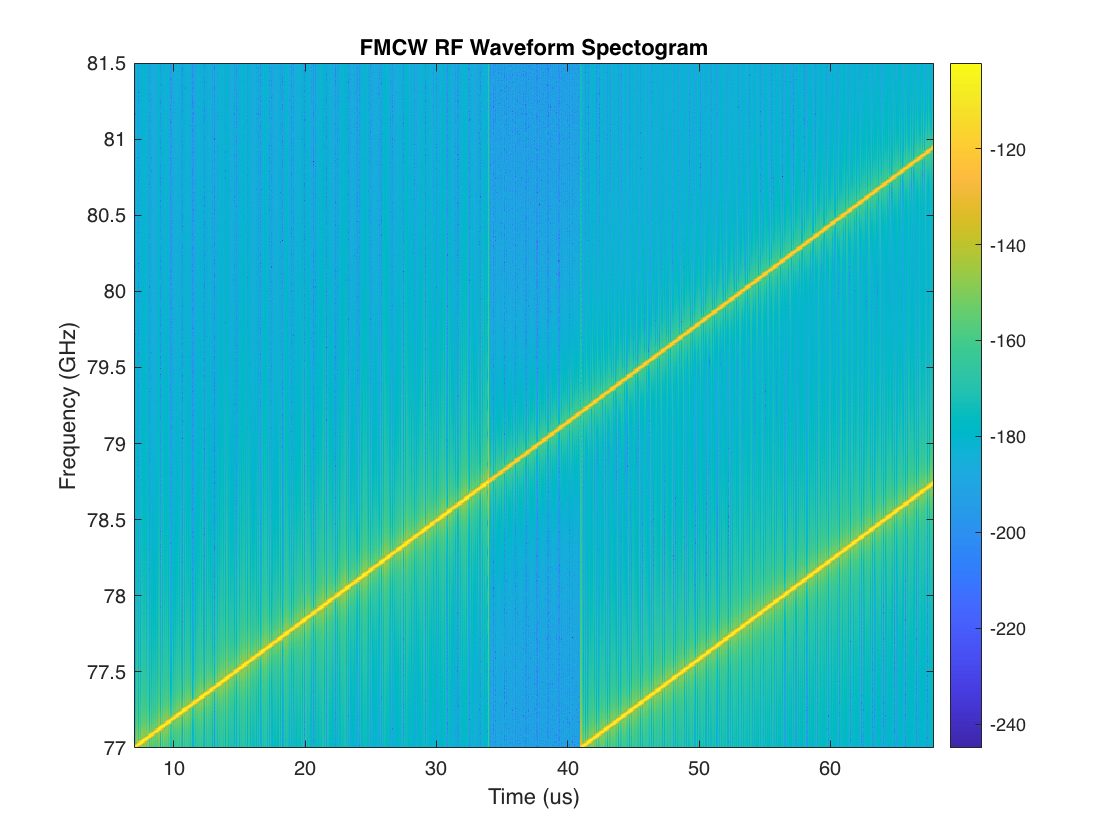

clf;
ax = axes;

simulator.load_default_defender_params;
simulator.load_default_attacker_params;

simulator.configure_FMCW_parameters();

defender_frame = 1;
defender_chirp = 1;

%load default target, attacker, and defender positions and velocities
simulator.load_target_default();
simulator.load_default_attacker_and_defender_position_and_velocity();

[sampled_IF_sig,combined_received_sigs, defender_waveform_sig, defender_waveform_t] = simulator.FMCW_simulate_scenario_chirp(defender_chirp,defender_frame);
simulator.plot_RF_spectogram(ax,combined_received_sigs,simulator.Defender.FMCW_sampling_rate_Hz,defender_waveform_t);

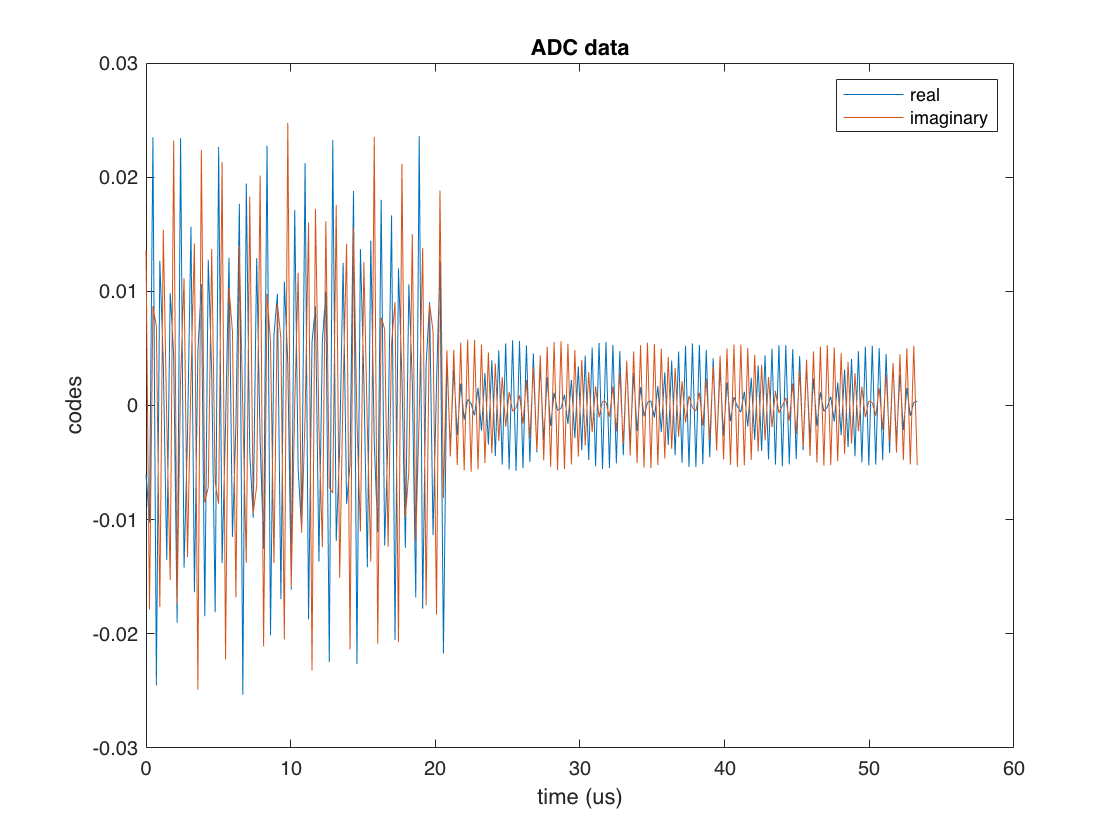

clf;
ax = axes;
simulator.FMCW_plot_sampled_IF_data(ax, simulator.Defender, sampled_IF_sig);

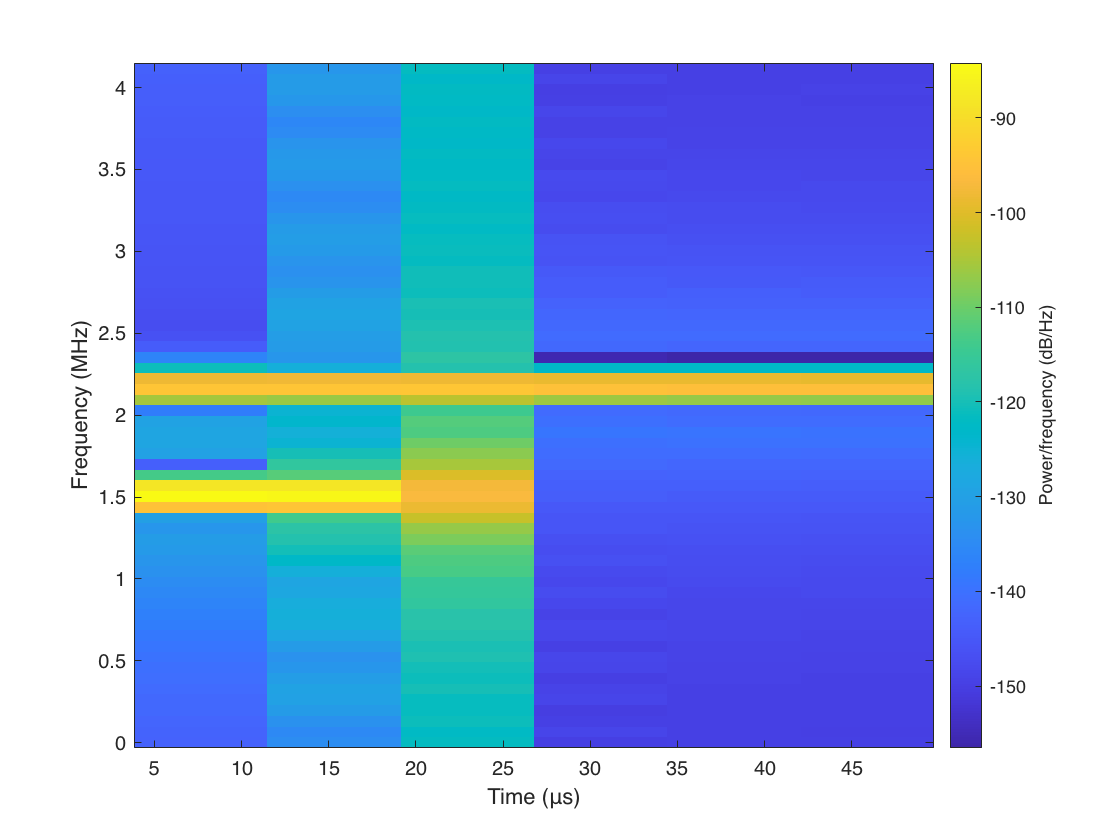

clf;
ax = axes;
simulator.plot_IF_spectogram(ax,sampled_IF_sig,simulator.Defender.ADC_SampleRate_MSps * 1e6);

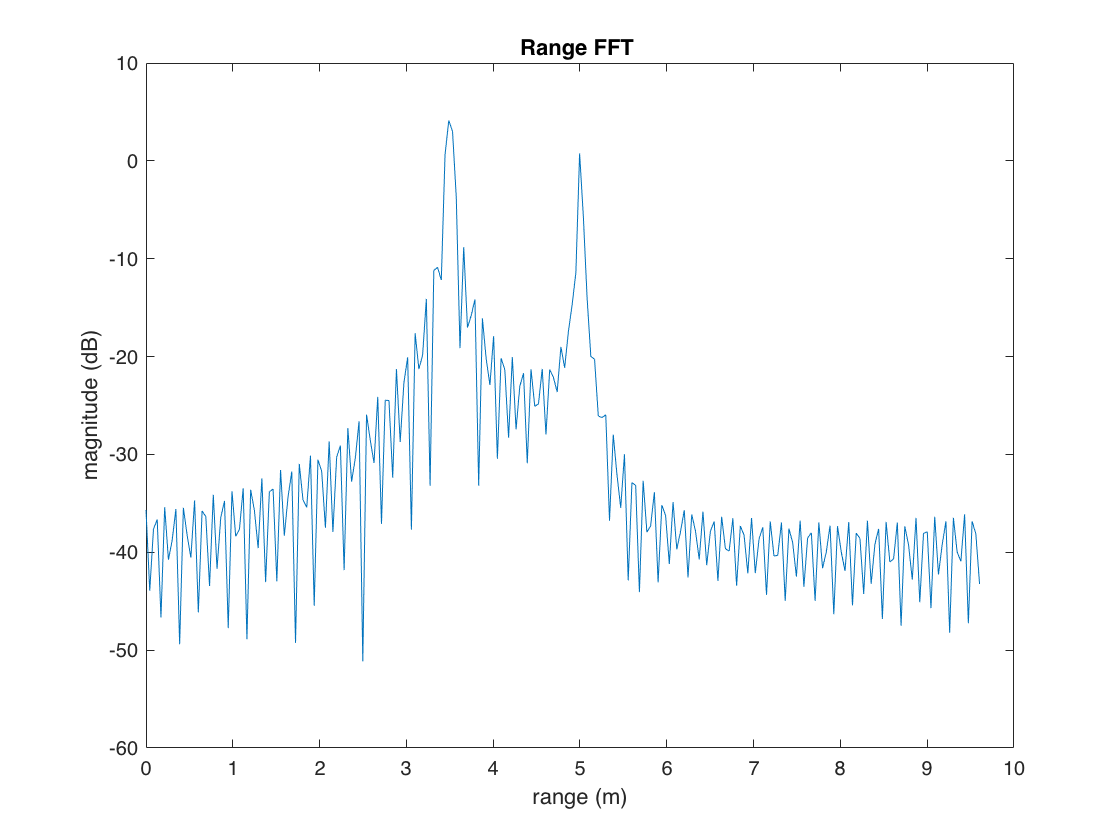

clf;
ax = axes;
simulator.FMCW_plot_range_fft(ax,simulator.Defender,sampled_IF_sig);